# Lab 4 control of the Quanser 2dof 

**Guidelines : fill in blank matlab code area and (...) text zones**

The goal of this lab is to design a simple control law for the pitch angle. We will design a Proportional Derivative controller. We will do this design following a two steps approach :

- The design of an inner loop for the control of the rotation speed,

- The design of an outer loop for the control of the angle.

**The final requierment is a closed loop bandwidth between **$2\;\textrm{rad}\ldotp s^{-1}$ **and** $2\ldotp 5\;\textrm{rad}\ldotp s^{-1}$

Notations:

- control reference: theta_ref (rad), reference angle

- control inout: u (V), input voltage

- outpout 1 : theta (rad), pitch angle

- outpout 2 : thetad (rad/s), pitch angle derivative

The starting point is the full non linear model obtained in the last lab. The system has one input (the violtage u) and two outputs (the angle theta and the rotaiton speed thetad).

clear all;clc;
QuanserData;    % Load data of the model
open('ControlMec.slx')

### 1 : Model linearization

As in lab 3 we first extract a linear model from the full non linear model.

x0=[];
u0=0;%Input is initialized at 0V
y0=[]; 
ix=[];
iu=1; %Input 1 is freezed
iy=[];
[xtrim,utrim,ytrim,dxtrim] = trim('ControlMec',x0,u0,y0,ix,iu,iy);
[Amec,Bmec,Cmec,Dmec] = linmod('ControlMec', xtrim, utrim);
Gmec=ss(Amec,Bmec,Cmec,Dmec);

This system has two outputs. We can extract two models : F1 from u to theta and F2 from u to thetad:

F1 = Gmec(1,1) % Model from u to theta

F1 =
 
  A = 
              x1         x2         x3         x4
   x1          0          1          0          0
   x2     -3.726    -0.3302   0.002055  -0.002055
   x3          0          0     -1.213          0
   x4          0          0          0     -1.213
   x5          0          0     -36.21          0
   x6          0          0          0     -36.21
 
              x5         x6
   x1          0          0
   x2          0          0
   x3       3749          0
   x4          0       3749
   x5      -7241          0
   x6          0      -7241
 
  B = 
           u1
   x1       0
   x2       0
   x3       0
   x4       0
   x5   862.1
   x6  -862.1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



F2 = Gmec(2,1) % Modeml from u to thetad

F2 =
 
  A = 
              x1         x2         x3         x4
   x1          0          1          0          0
   x2     -3.726    -0.3302   0.002055  -0.002055
   x3          0          0     -1.213          0
   x4          0          0          0     -1.213
   x5          0          0     -36.21          0
   x6          0          0          0     -36.21
 
              x5         x6
   x1          0          0
   x2          0          0
   x3       3749          0
   x4          0       3749
   x5      -7241          0
   x6          0      -7241
 
  B = 
           u1
   x1       0
   x2       0
   x3       0
   x4       0
   x5   862.1
   x6  -862.1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   1   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



We transform F1 and F2 (state space models) into transfer function

F1 = tf(F1);
F2 = tf(F2);

We compute the minimal realization (pole-zero compensation)

tol = 1e-6; %tolerance for pole-zero compenssation (default is 1e-8)
F1 = minreal(F1,tol);
F2 = minreal(F2,tol);

## 2. Is it possible to control the angle with just a proportional controller?

We want to explore the possibility of designing a simple proportional controler. The control law will be:


$$u=k_p \times \;\left({\textrm{theta}}_{\textrm{ref}} -\textrm{theta}\right)$$


**Question 1 **: Compute the poles of the open loop system. (Functions **pole**, **zero**, **damp**)

pole(F1)

ans = 	1.0e+03 *

  -7.2226 + 0.0000i
  -0.0200 + 0.0000i
  -0.0002 + 0.0019i
  -0.0002 - 0.0019i


zero(F1)


ans =

  0×1 empty double column vector



damp(F1)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.65e-01 + 1.92e+00i     8.55e-02       1.93e+00         6.06e+00    
 -1.65e-01 - 1.92e+00i     8.55e-02       1.93e+00         6.06e+00    
 -2.00e+01                 1.00e+00       2.00e+01         5.00e-02    
 -7.22e+03                 1.00e+00       7.22e+03         1.38e-04    


**Question 2 **: is the open loop system well damped?

If we look at the damping values of the system, 2 values are less than 1 (underdamped) while the other 2

equal to 1 (critical damping). Therefore, the system as a whole is not well damped. We can check the step response as well to gauge the stability of the system. It consists of several oscillations which makes it not well damped.

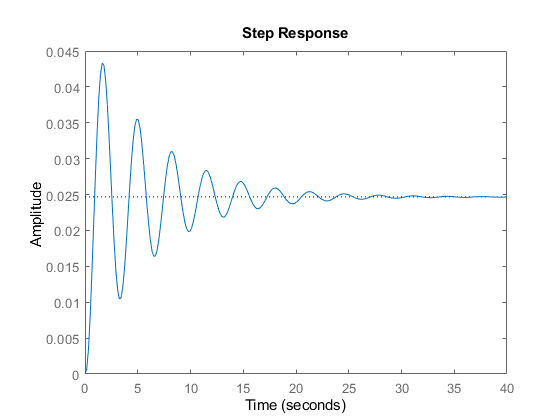

step(F1)

**Question 3 **: what happens (in term of damping) if we close the loop with a pure proportional controller? (you can use the **rlocus** Matlab function)

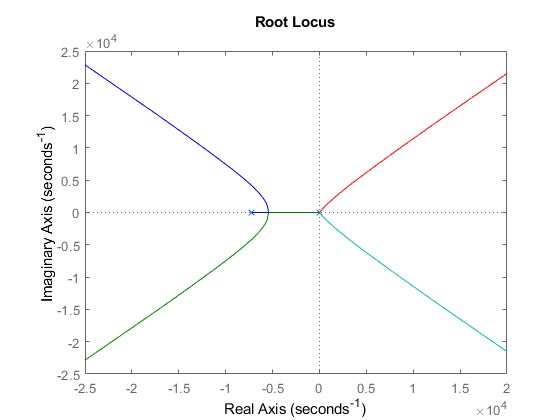

rlocus(F1)

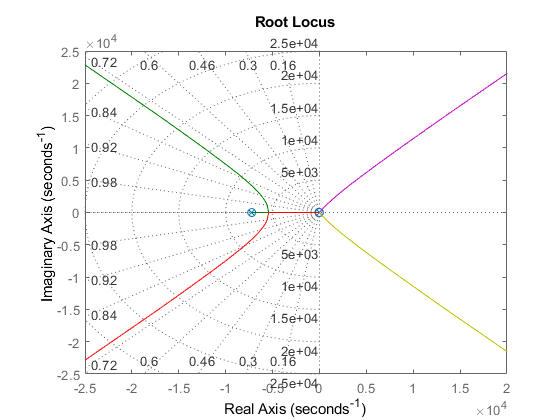

Cl = F1/(1+F1);
kp1=10000;
Cl=Cl*kp1;
rlocus(Cl)
grid on

When we close the loop, as we increase kp1, the poles tend towards the positive real part and the system becomes more unstable and the damping decreases. We need a derivative effect as well, it will not be possible to model this system with a purely proportional controller.

**Question 4 **: what is value of kp that makes the closed loop system unstable? (**bode**, **margin**) 

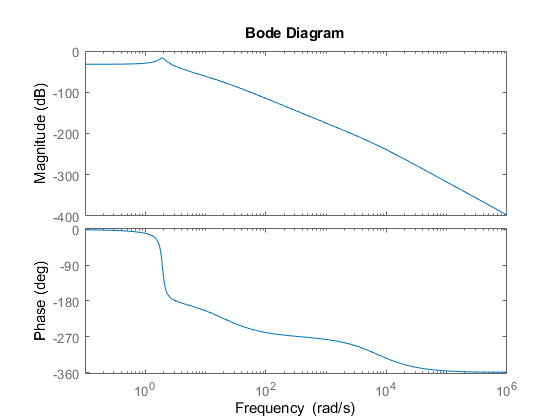

bode(F1)

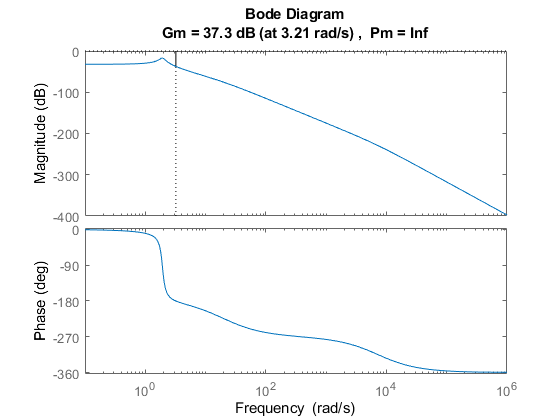

margin(F1)


% Gain margin is obtained when the phase reaches -180 deg
K = (10)^(37.3/20)

K = 73.2825

## 3. Design of a inner speed control loop

The classical solution is to add a derivative effect in order to increase the damping factor. Instead of designing a PD controller directly we will design it in two steps: first a derivative (inner) loop and then a proportional (outer) loop.

The final requierement for the closed loop bandwidth being 2 rad/s we must choose a higher bandwidth for the inner loop:

**The requirement for the inner closed loop bandwidth is **$7\;\textrm{rad}\ldotp s^{-1}$

The transfer function between the control input and the rotation speed is $F_2$

### 3.1 Find an appropriate simple model

**Question 5 **: find (trial and errors) a model $F_{2\;\textrm{simple}} =\frac{G}{s}$ that best fits the transfer function $F_2$ in the frequency range of 5 to 10 rad/s.

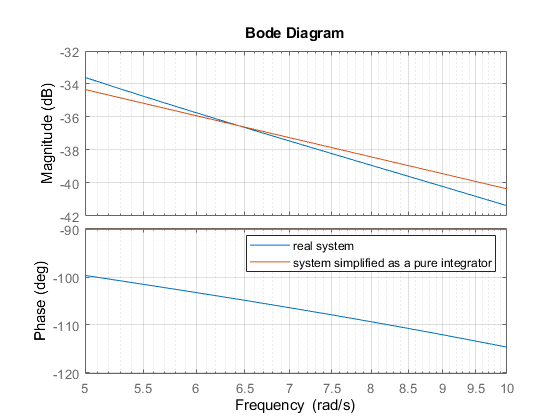

% Trick: we define a transfer function 's' corresponding to the Laplace
% variable
s = tf('s');
G = 0.096; % Must be tuned
F2s = G/s;
bode(F2,F2s,{5,10}) % plot the bode diagram in the range 1-10 rad/s
legend('real system', 'system simplified as a pure integrator')
grid on;

(...)

### 3.2 Design a closed loop derivative controller

**Question 6 :** What is the value of the proportional gain kv that gives a closed loop bandwidth of 7 rad/s ? (kv is proportional to the velocity, it is our "derivative" term). You can read the answer in the bode diagram of the simplified model F2s or compute by hand (or both!)

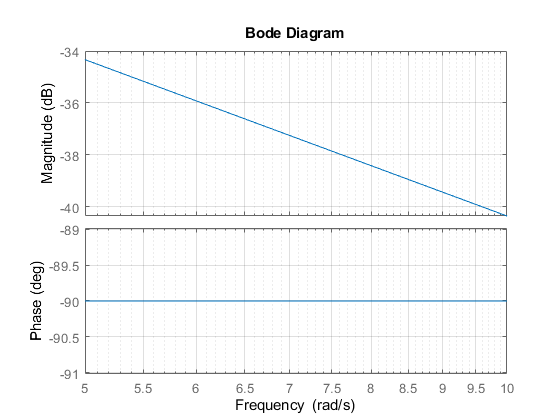

bode(F2s,{5,10})
grid on;

kv = 10^(37.3/20) % at 7 rad/s

kv = 73.2825

F2s = F2s/(1+kv*F2s)

F2s =
 
     0.096 s
  -------------
  s^2 + 7.035 s
 
Continuous-time transfer function.



**Question 7 : **What is the time constant of the inner loop?

damp(F2s)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -7.04e+00     1.00e+00       7.04e+00         1.42e-01    


% time constant = 0.201 seconds

## 4. Design the outer proportional loop

The inner derivative loop with the gain kv obtained at question 3.2 corresponds to this diagram:

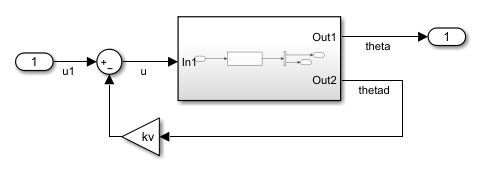

### 4.1 Compute a model

**Question 8 : **Find the transfer function H between u1 and theta. (Will depend of F2 and kv)

H = F2/(1+kv*F2)*(1/s)

H =
 
                                                            
  1.328e04 s^5 + 9.621e07 s^4 + 1.951e09 s^3 + 9.923e08 s^2 
                                                            
                                             + 7.152e09 s   
                                                            
  ----------------------------------------------------------
                                                          
   s^9 + 1.449e04 s^8 + 5.275e07 s^7 + 2.129e09 s^6       
                                                          
           + 2.972e10 s^5 + 1.728e11 s^4 + 2.365e11 s^3   
                                                          
                               + 6.045e11 s^2 + 2.899e11 s
                                                          
 
Continuous-time transfer function.



### 4.2 Tune a proportional controller

**Question 9 :** Plot the bode diagram of H and verify that a proportional controller will do the job (closed loop bandwidth of 2 rad/s). What is the corresponding value of kp ?

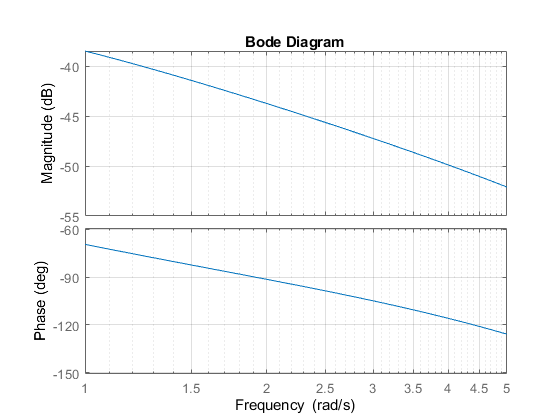

bode(H,{1,5})
grid on;

kp = 10^(38/20)

kp = 79.4328

One can read on the Bode diagram that for a closed loop of 20 rad/s the correct value for kp is 

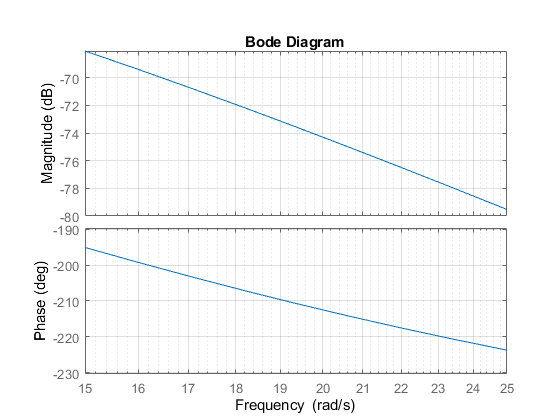

bode(H,{15,25})
grid on;

kp1 = 10^(74.8/20)

kp1 = 5.4954e+03

### 4.3 Analyse the time domain performance

The controller is now totally designed. The closed loop diagram is the following:

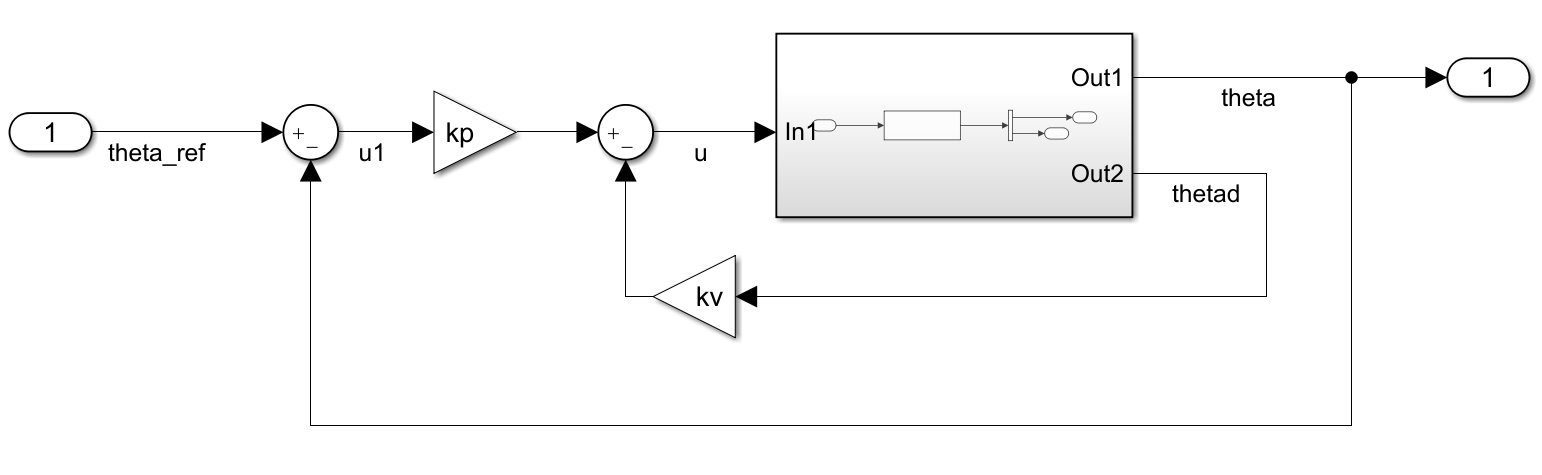

**Question 10 :** Compute the closed loop transfer function CL (between theta_ref and theta) (will depend on kp, kv, F1 and F2)

CL = kp*F1/(1+kp*F1+kv*F2)

CL =
 
                                                            
  1.055e06 s^8 + 1.528e10 s^7 + 5.566e13 s^6 + 2.246e15 s^5 
                                                            
          + 2.392e16 s^4 + 3.139e16 s^3 + 1.728e17 s^2      
                                                            
                                  + 8.488e16 s + 3.059e17   
                                                            
  ----------------------------------------------------------
                                                          
   s^12 + 2.173e04 s^11 + 1.578e08 s^10 + 3.863e11 s^9    
                                                          
           + 2.32e13 s^8 + 5.322e14 s^7 + 5.861e15 s^6    
                                                          
           + 3.271e16 s^5 + 9.195e16 s^4 + 2.33e17 s^3    
                                                          
                      + 3.879e17 s^2 + 4.32e17 s + 4.62e17
                                 

**Question 11 : **Analyse the performance of the controlled system (time response, overshoot, etc.) (Matlab functions **step** and **stepinfo**)

What is the dc gain of the controlled system? (Matlab function **dcgain**). Is that good? How could we reduce (or cancel) the static error?

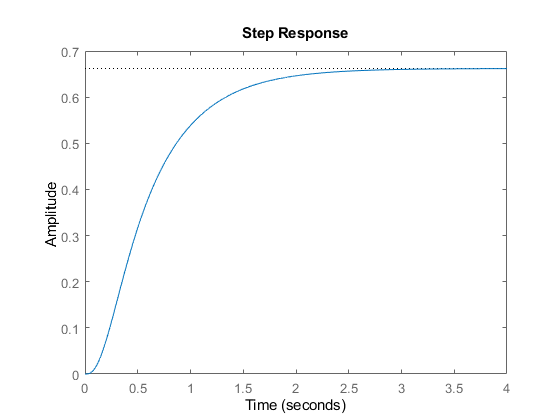

step(CL)

stepinfo(CL)

ans = struct with fields:
        RiseTime: 1.1125
    SettlingTime: 2.0888
     SettlingMin: 0.5959
     SettlingMax: 0.6619
       Overshoot: 0
      Undershoot: 0
            Peak: 0.6619
        PeakTime: 4.1282


dcgain(CL)

ans = 0.6621

## 5. Final performance (simulation)

### 5.1 Simulink model

**Question 12 : **Program (in Simulink) the closed loop system (with kp and kv) with the full non linear model. Name it **ControlMecCL.slx**

### 5.2 Time domain performance

**Question 13 : **Plot the step response (for a 10° step) of the full non-linear system in closed loop. Compare with the step response of the linear model in closed loop.

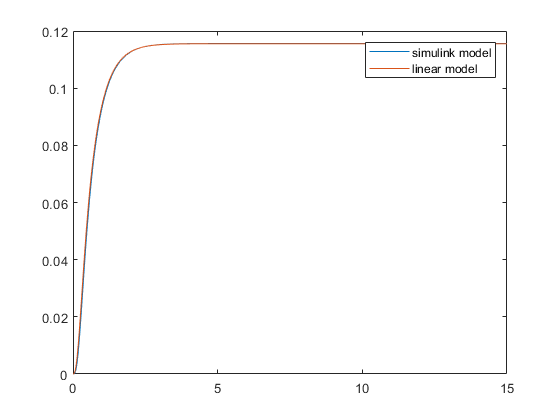

thetaRef = 10; % reference for the step
simout=sim('ControlMecCL.slx','OutputSaveName','yout');
[y,t] = step(thetaRef*pi/180*CL,15);
plot(simout.tout,simout.yout{1}.Values.Data,t,y);legend('simulink model','linear model');

The slight difference in the plot can be attributed to the fact that the calculation of kv and kp has been done using approximate values of gain.

### 5.2 Control voltage limitation

**Question 14 : **The input voltage is limited at +/-24V. Does this limit the preformance of the closed  loop? 

An input voltage of a maximum of 24V will limit the performance because a drone modelled from such a system (for example) will not be able to counterbalance the resistive forces such as gravity. It will not have enough power to do so.